# Distribution Tests: an analysis to assess the details of the distributions and compare them accross conditions. Used to generate figure 2 of SFN poster.

Here we run multiple types of statistical tests of distribution differences beyond simple ttests

- analyses can be performed by averaging accross channels (global anayslis  as performed in original figure) or including channel data (except for path length of course)

- detailed plots of distributions, including histograms and their fits, PDFs, CDFs, and QQ plots

Furthremore, there are some added benefits 

- Results of analysis are display in figure, so no errorrs due to copying/pasting the wong output on screen,

- Each condition is plotted in an appropriate color, so that no modification is needed when in adobe illustrator 

- baseline bounds are shown 

- validation functions and data descriptions to avoid analyzing wrong data

## First retreive Master Data Set

close all force
cog_task_list = {'PVT'};
DF = dfmaster('cogtestlist',cog_task_list);


Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done


# Run Analysis

Choose what to analyze

clearvars -except DF
clc;
close all force
cogtask         = 'PVT';
ntwprop         = 'pathl'; 
fsband          = 'delta';

% The analysis takes some time. You can modify the settings to only analyze
% what you want 
keepnodedata = false; % you can analyze distributions that include node data, or averaged accross nodes
runs2analyze = 1:4; % 1 2 3 or 4, or all
plotdistdetials = true; % you can plot PDF + CDFs + QQ plots for each run, or just spit out the test results

Get data set

if not(keepnodedata)
    str_node = sprintf('NOTE: This is the ORIGINAL FIG2 Analysis, where %s is averaged accross channels',upper(ntwprop));
else
    str_node = sprintf('NOTE: This is different to the FIG2 Analysis, since %s of EACH channel is assessed rather than averaged',upper(ntwprop));
end
df = dfmastersplit(DF, cogtask, {'baseline', 'control', 'light'}, fsband, runs2analyze,"keepchannels",keepnodedata);


!!!!!Note that only "good" subjects from the PVT task are in this data frame
!!!!!Note that you have averaged accross channels. Path length var is included in the data frame


 Runs Tests and plot Information and distributions

res_num = cell(4,1);
res_str = cell(4,1);

gettimepointdf = @(timepoint) df(ismember(df.run, [0 timepoint]),:); 
for t = runs2analyze
    df_run    = gettimepointdf(t);      
    [~,res_str{t},res_num{t}] = runmultitests(df_run,ntwprop,'printAllResults',false,'compareconditions',true);  
end


Plot Results

F = figure('Visible','on','Position', [1000 231 1249 1091]);
F_tl = tiledlayout(5,6);
boxcenters = [runs2analyze; runs2analyze+.33];


Generate Figure 2 Box Plot but overlaying the error of the baseline condition

ax_box_Fig2 = nexttile(1,[1 4]); 
ax_box_Fig2.Color = [.8 .8 .8];
ax_box_Fig2.XLim = [.66,max(boxcenters(:))+.33];
ax_box_Fig2.NextPlot = 'add';
box off

% Lets overlay the IQR during presleep
med = prctile( df.(ntwprop)(df.condition == 'baseline'),50);
iqb  = prctile( df.(ntwprop)(df.condition == 'baseline'),[25 75]);
[l,p] = boundedline(xlim, [med med], abs(med - iqb), ':k');
outlinebounds(l,p);
p.FaceColor = 'k';
p.FaceAlpha = .5;

% Make box plots but remove the baseline
b = boxchart(df.run,df.(ntwprop), 'GroupByColor',df.condition,'MarkerStyle','.');

b(ismember({b.DisplayName},'control')).BoxFaceColor = [1 0 0];
b(ismember({b.DisplayName},'control')).BoxFaceAlpha = .9;
b(ismember({b.DisplayName},'control')).BoxLineColor = 'k';
b(ismember({b.DisplayName},'control')).WhiskerLineColor = 'k';

b(ismember({b.DisplayName},'light')).BoxFaceColor = 'y';
b(ismember({b.DisplayName},'light')).BoxFaceAlpha = .9;
b(ismember({b.DisplayName},'light')).MarkerColor = 'y';
b(ismember({b.DisplayName},'light')).BoxLineColor = 'k';
b(ismember({b.DisplayName},'light')).WhiskerLineColor = 'k';
delete ( b(ismember({b.DisplayName},'baseline')) );

% Add stars and p values to conditions that differ    
for t = runs2analyze
    plotsigstars(res_num, t,'controlvslight',b,ax_box_Fig2,boxcenters)  ;  
    plotsigstars(res_num, t,'control',b,ax_box_Fig2,boxcenters);  
    plotsigstars(res_num, t,'light',b,ax_box_Fig2,boxcenters);  
end

% Finalize the Figure  
ax_box_Fig2.XTick = mean(boxcenters);
ax_box_Fig2.XTickLabels = {'t_1','t_2','t_3','t_4'};
ax_lgd = legend({'Presleep IQR','','','Control','Light'},'Location','bestoutside','Box','off');

ylabel_str = sprintf('%s %s', (fsband), upper(ntwprop));
ylabel(ylabel_str)
title(strcat(ylabel_str, sprintf(' after waking')))




Plot Details of Test results, and details of histograms if desired

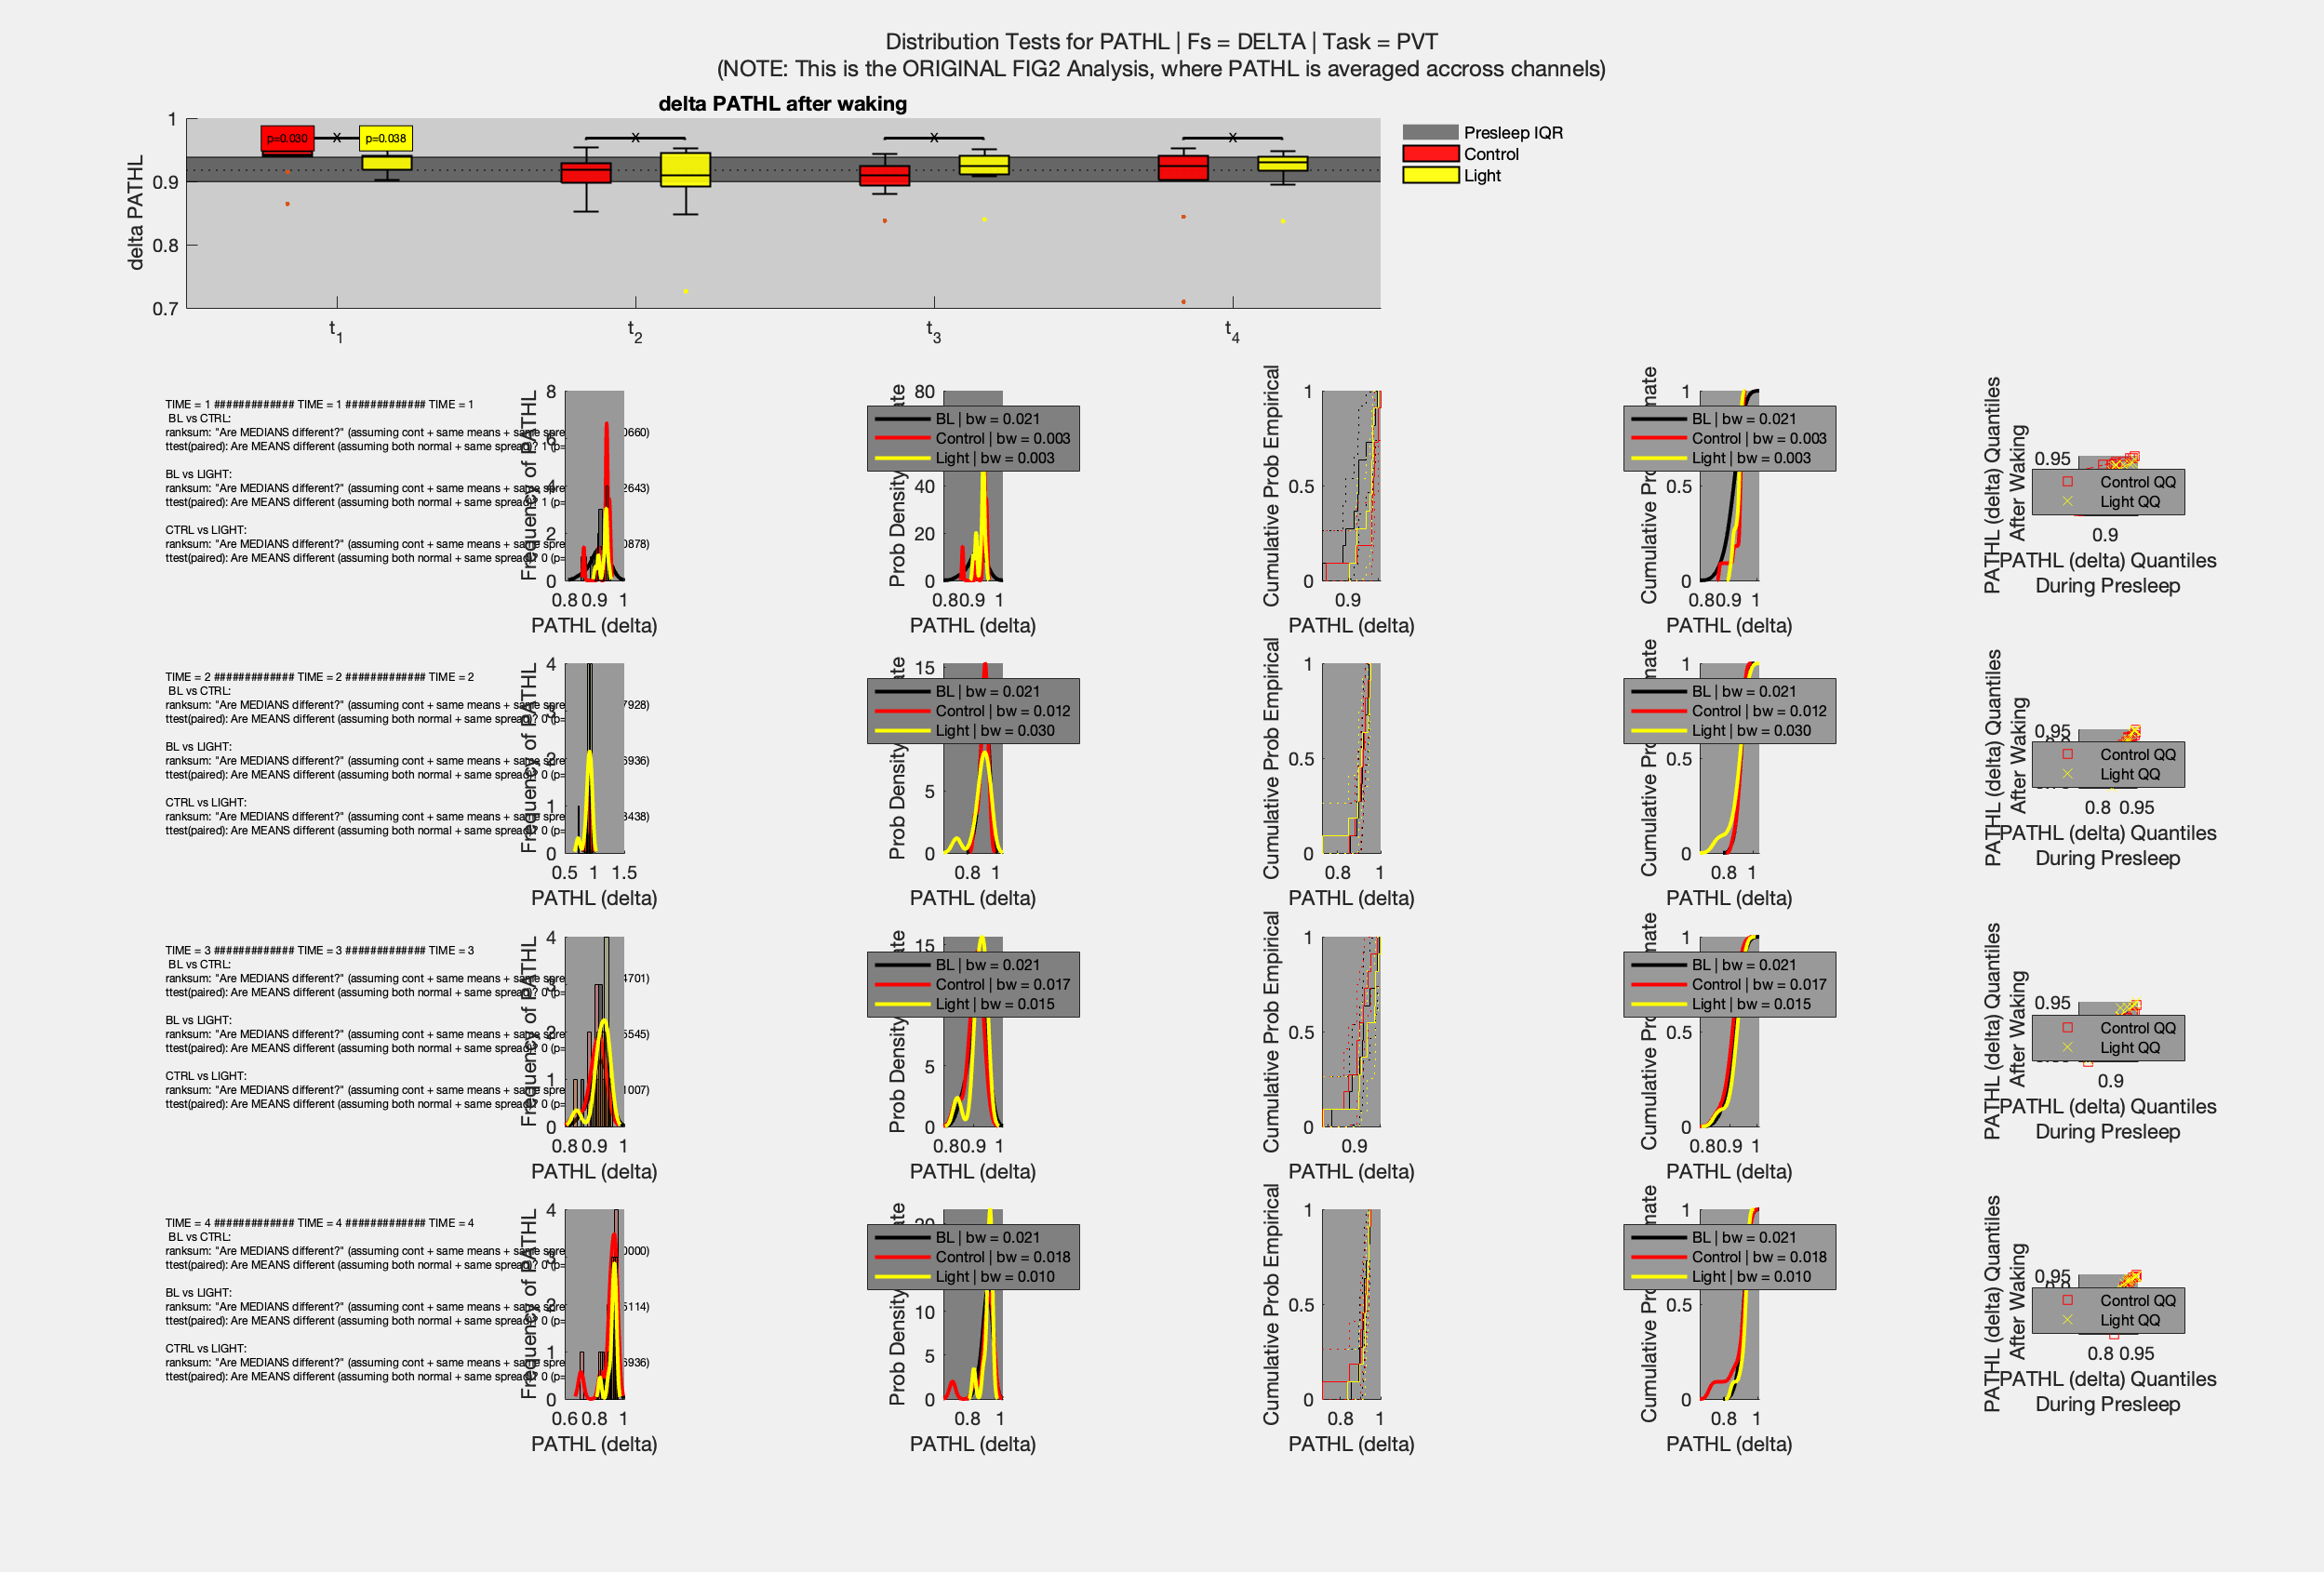

plt_rowidx = [6 11 16 21];
for t = runs2analyze
    ax_info = nexttile(plt_rowidx(t)+t);
    axis off  

    df_run    = gettimepointdf(t);      
    run_str = sprintf('TIME = %d ############# TIME = %d ############# TIME = %d\n\t%s',t,t,t,res_str{t});
    text(ax_info, -.35,.45, run_str, 'units', 'normalized','HorizontalAlignment','left', 'FontSize',6,'VerticalAlignment','middle');
    
    if (plotdistdetials)
        ax_hist = nexttile(plt_rowidx(t)+t+1);
        plotHistEmpir(df_run,ntwprop,ax_hist);
    
        ax_pdfest = nexttile(plt_rowidx(t)+t+2);
        plotPdfEstim(df_run,ntwprop,ax_pdfest);
    
        ax_cdfemp = nexttile(plt_rowidx(t)+t+3);    
        plotCdfEmpir(df_run,ntwprop,ax_cdfemp);
    
        ax_CdfEstim = nexttile(plt_rowidx(t)+t+4);    
        plotCdfEstim(df_run,ntwprop,ax_CdfEstim)
    
        ax_qq = nexttile(plt_rowidx(t)+t+5);        
        plotQQ(df_run,ntwprop,ax_qq)
    end
end


% Figure Title
str_varinfo = sprintf('Distribution Tests for %s | Fs = %s | Task = %s',upper(ntwprop), upper(fsband), cogtask);
str_title = sprintf('%s\n(%s)',str_varinfo,str_node);
title(F_tl, str_title,'FontSize',12);  

# Function to plot significant stars

function plotsigstars(res_num, t,cond_compare,b,ax,boxcenters)
    switch upper(cond_compare)
        case 'CONTROL'
            cond_name = 'control';
            cond_idx = 1;
            cond_clr = 'r';
        case 'LIGHT'
            cond_name = 'light';
            cond_idx = 2;
            cond_clr = 'y';
        case 'CONTROLVSLIGHT'
            cond_name = 'controlVslight';
            cond_idx = 3;
            cond_clr = 'b';
        otherwise
            error('')
    end

    pval = res_num{t}.(cond_name).ttest_p;
    pval_str = sprintf('%.03f',pval);


axes(ax)
    if strcmpi(cond_name,'light') || strcmpi(cond_name,'control')         
        if pval<.05
            mu = std(cat(1,b(2:3).YData));
            s = mean(cat(1,b(2:3).YData));               
            text(ax,boxcenters(cond_idx,t), mu+s,  sprintf('p=%.03f',pval),...
                'HorizontalAlignment','center','VerticalAlignment','bottom',...
                'Color','k','EdgeColor','k','BackgroundColor',cond_clr,...
                'FontSize',6);
        else

        end
    elseif strcmpi(cond_name,'controlVslight')
        if pval<.05
            ax_star = sigstar({boxcenters(1:2,t)},pval);
            ax_star = findobj(ax_star);
            ax_star(2).String = sprintf('%s (%s)\n',ax_star(2).String,pval_str); 
        else
            ax_star = sigstar({boxcenters(1:2,t)},pval);
            ax_star = findobj(ax_star);
            ax_star(2).String = 'X';            
        end
        ax_star(2).FontSize = 7;        
    else
        error('')

    end

end

# Plot Distribution Properties

function plotHistEmpir(df,ntwprop,ax)
    arguments 
        df
        ntwprop
        ax
    end
    [bl, cntl,light,run,cogtest,band] = validateandsplit(df,ntwprop);


    % Init
    xlabel_str = sprintf('%s (%s)',upper(ntwprop),(band));    
    ax_backcolor = [.6 .6 .6];
    set(ax,'NextPlot','add','Color',ax_backcolor)
   

    %  plot empirical histograms 
    ax_plt_bl = histfit(ax, bl,10, 'kernel');
    ax_plt_bl(1).FaceColor = 'k';
    ax_plt_bl(1).FaceAlpha = .4;
    ax_plt_bl(2).Color = 'k';

    ax_plt_cntl = histfit(ax,cntl,10, 'kernel');
    ax_plt_cntl(1).FaceColor = 'r';
    ax_plt_cntl(1).FaceAlpha = .2;
    ax_plt_cntl(2).Color = 'r';

    ax_plt_light = histfit(ax,light,10, 'kernel');
    ax_plt_light(1).FaceColor = 'y';
    ax_plt_light(1).FaceAlpha = .1;
    ax_plt_light(2).Color = 'y';
    ylabel(ax,sprintf('Frequency of %s',upper(ntwprop)));
    xlabel(ax,xlabel_str)    
    title_str = sprintf('Empirical and smoothed Frequency distribution ');

end

function plotPdfEstim(df,ntwprop,ax)
    arguments 
        df
        ntwprop
        ax
    end

    [bl, cntl,light,run,cogtest,band] = validateandsplit(df,ntwprop);
   
    % Initiate
    xlabel_str = sprintf('%s (%s)',upper(ntwprop),(band));    
    ax_backcolor = [.6 .6 .6];
    set(ax,'NextPlot','add','Color',ax_backcolor)
   
    % Plot Estimated PDFs
    [f,xi,bl_bw] = ksdensity(ax,bl);
    plot(ax,xi,f, 'k', 'LineWidth',2); 
    [f,xi,cntl_bw] = ksdensity(ax,cntl); 
    plot(ax,xi,f, 'r', 'LineWidth',2); 
    [f,xi,light_bw] = ksdensity(ax,light); 
    plot(ax, xi,f, 'y', 'LineWidth',2); 
    ax.Color = [.5 .5 .5];
    
    title_str        = sprintf('Probability density *Estimate*');
    legend(ax,{sprintf('BL | bw = %.03f',bl_bw),...
        sprintf('Control | bw = %.03f',cntl_bw),...
        sprintf('Light | bw = %.03f',light_bw)},...
        'FontSize',8,'Location','best');   
    xlabel(ax,xlabel_str)
    ylabel(ax,'Prob Density Estimate')


end

function plotCdfEmpir(df,ntwprop,ax_cdfemp)
    arguments 
        df
        ntwprop
        ax_cdfemp
    end

    [bl, cntl,light,run,cogtest,band] = validateandsplit(df,ntwprop);

    % Init
    ax_backcolor = [.6 .6 .6];
    set(ax_cdfemp,'NextPlot','add','Color',ax_backcolor)  
    set(ax_cdfemp,'NextPlot','add','Color',ax_backcolor);

    % Plot CDF Empirical
    ecdf(ax_cdfemp,bl, 'Bounds','on');
    ax_cdfemp.Children(1).Color = 'k';
    ax_cdfemp.Children(2).Color = 'k';
    ax_cdfemp.Children(3).Color = 'k';
    
    ecdf(ax_cdfemp,cntl, 'Bounds','on');
    ax_cdfemp.Children(1).Color = 'r';
    ax_cdfemp.Children(2).Color = 'r';
    ax_cdfemp.Children(3).Color = 'r';
    
    ecdf(ax_cdfemp,light,'Bounds','on');
    ax_cdfemp.Children(1).Color = 'y';
    ax_cdfemp.Children(2).Color = 'y';
    ax_cdfemp.Children(3).Color = 'y';

    ylabel(ax_cdfemp,'Cumulative Prob Empirical') 
    xlabel_str = sprintf('%s (%s)',upper(ntwprop),(band));    

    xlabel(ax_cdfemp,xlabel_str)

end

function plotCdfEstim(df,ntwprop,ax_cdfEstim)
    arguments 
        df
        ntwprop
        ax_cdfEstim
    end

    [bl, cntl,light,run,cogtest,band] = validateandsplit(df,ntwprop);

    % Init
    xlabel_str = sprintf('%s (%s)',upper(ntwprop),(band));    
    ax_backcolor = [.6 .6 .6];
    set(ax_cdfEstim,'NextPlot','add','Color',ax_backcolor)

 
%     % Plot Estimated CDFs
    [f,xi,bl_cdf_bw] =  ksdensity(ax_cdfEstim,bl,'Function','cdf','NumPoints',50);
    plot(ax_cdfEstim,xi,f,'-k','LineWidth',2)
    
    [f,xi,cntl_cdf_bw] =  ksdensity(ax_cdfEstim,cntl,'Function','cdf','NumPoints',50);
    plot(ax_cdfEstim,xi,f,'-r','LineWidth',2)
    
    [f,xi,light_cdf_bw] =  ksdensity(ax_cdfEstim,light,'Function','cdf','NumPoints',50);
    plot(ax_cdfEstim,xi,f,'-y','LineWidth',2)

    title_str = sprintf('CDF *Estimate*,');
    legend(ax_cdfEstim,{sprintf('BL | bw = %.03f',bl_cdf_bw),...
        sprintf('Control | bw = %.03f',cntl_cdf_bw),...
        sprintf('Light | bw = %.03f',light_cdf_bw)},...
        'Location','best','FontSize',8);            
    ylabel(ax_cdfEstim,'Cumulative Prob Estimate')    ;
    xlabel(ax_cdfEstim,xlabel_str);

end

function plotQQ(df,ntwprop,ax_qq)
    arguments 
        df
        ntwprop
        ax_qq
    end

    [bl, cntl,light,run,cogtest,band] = validateandsplit(df,ntwprop);


    % Init
    ax_backcolor = [.6 .6 .6];
    set(ax_qq,'NextPlot','add','Color',ax_backcolor)


    % QQ Plots
    q = qqplot(ax_qq,bl,bl);
    q(1).Marker = 'none';
    q(1).MarkerEdgeColor = 'k';
    q(2).Color= 'k';
    q(3).Color= 'k';
    
    q = qqplot(ax_qq,bl,cntl);
    q(1).Marker = "square";
    q(1).MarkerEdgeColor = 'r';
    q(2).Color= 'r';
    q(3).Color= 'r';
    
    q = qqplot(ax_qq,bl,light);
    q(1).Marker = "x";
    q(1).MarkerEdgeColor = 'y';
    q(2).Color= 'y';
    q(3).Color= 'y';
    
    axis square
    [mn,mx] = bounds([bl;cntl;light]);
    xlim(ax_qq,[mn,mx]);
    ylim(ax_qq,[mn,mx]);
    
    xlabel(ax_qq, sprintf('%s (%s) Quantiles\nDuring Presleep',upper(ntwprop),band));
    ylabel(ax_qq, sprintf('%s (%s) Quantiles\n After Waking',upper(ntwprop),band));
    legend(ax_qq,{'','','','','','Control QQ','','','Light QQ'},'Location','Best','FontSize',8);
    
end

Function: Validate and Split Data Frame

function [bl, ctrl,light,run,cogtest,band] = validateandsplit(df,ntwprop)
    % Validate
    gs = groupsummary(df, {'cogtest','band_ord','condition','run'},...
        {'mean','median','std','min','max','nummissing','nnz'},ntwprop,"IncludeEmptyGroups",false);
    band = unique(gs.band_ord);
    cogtest = unique(gs.cogtest);
    run = unique(gs.run);
    run = run(run~=0);

    
    if ~all(ismember({'baseline','control','light'},df.condition))
        error('Data from all three groups need to be in the data frame')
    end

    if numel(cogtest)~=1 || numel(run)~=1 || numel(band)~=1
        error('LUIS: data can only contain one time point, one band, and one task')
    end

    % Split Data
    bl      = df.(ntwprop)( df.condition == "baseline");
    ctrl    = df.(ntwprop) (df.condition == "control");
    light   = df.(ntwprop)( df.condition == "light");

end